# Question 6

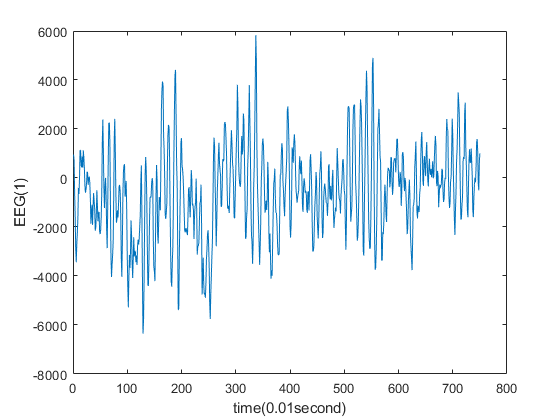

% Loading Signals
EEG = zeros(8, 750);
EEG(1, :) = load('eeg1-c3.dat');
EEG(2, :) = load('eeg1-c4.dat');
EEG(3, :) = load('eeg1-f3.dat');
EEG(4, :) = load('eeg1-f4.dat');
EEG(5, :) = load('eeg1-o1.dat');
EEG(6, :) = load('eeg1-o2.dat');
EEG(7, :) = load('eeg1-p3.dat');
EEG(8, :) = load('eeg1-p4.dat');


f_s = 100;
figure()
plot(EEG(1,:))
xlabel('time(0.01second)')
ylabel('EEG(1)')

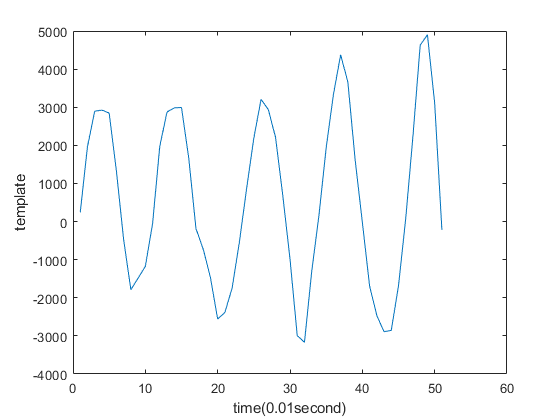


% Select pattern according to EEG(1)
template = EEG(1,505:555);
plot(template)
xlabel('time(0.01second)')
ylabel('template')

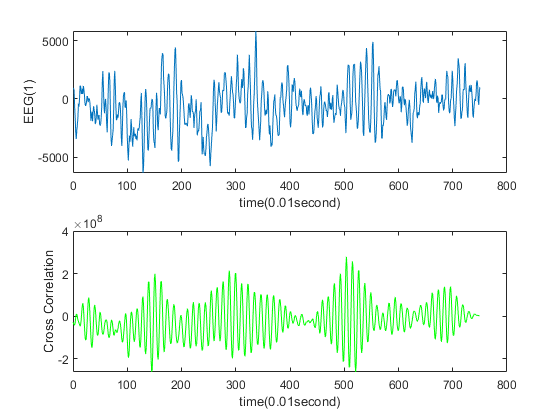

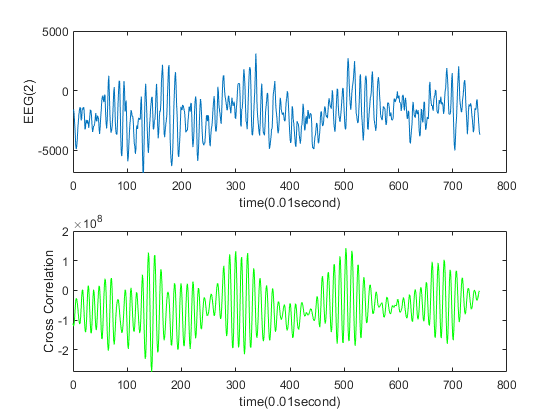

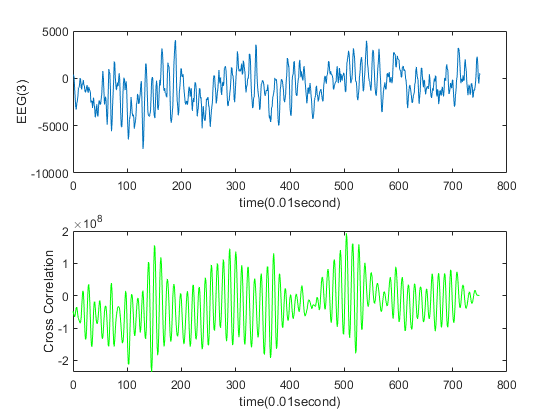

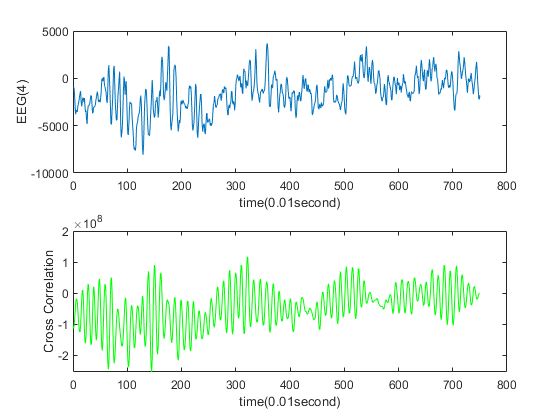

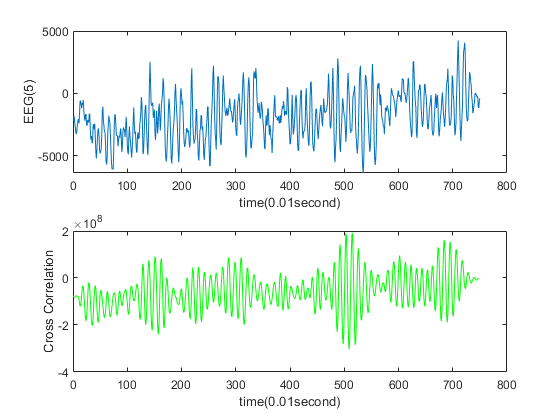

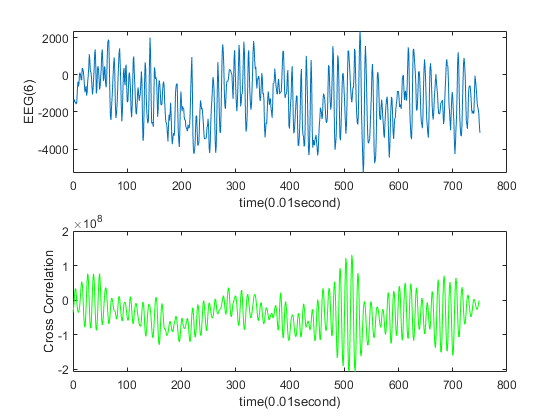

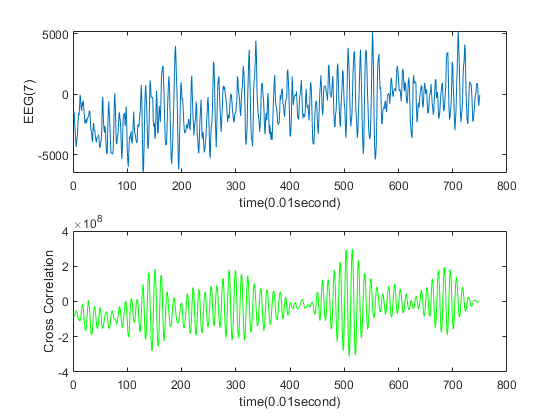

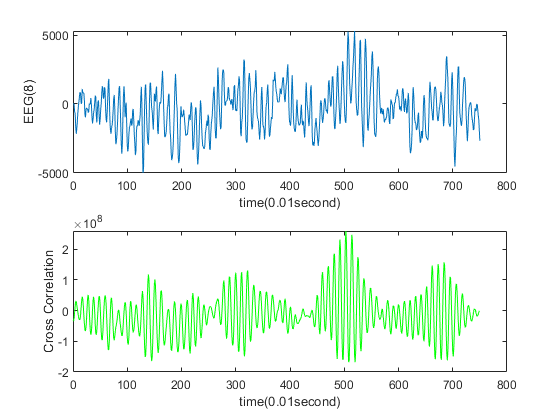


%Calculating & plotting Crosscorrelation
XC = zeros(8,1499);% Preallocating 
lags = zeros(8,1499);% Preallocating 
for i= 1:8
    figure(i)
    subplot(2,1,1); plot(EEG(i,:)) % Plot the EEG signal
    xlabel('time(0.01second)')
    ylabel(sprintf('EEG(%d)',i))
    [XC(i,:), lags(i,:)] = xcorr(EEG(i,:), template);
    for j = 750:length(XC(i,:))
        if (XC(i,j)<3*max(XC(i))/4 && XC(i,j)>-3*max(XC(i))/4)
           XC(i,j) = 0;
        end
    end
    subplot(2,1,2); plot(lags(i,750:1499), XC(i,750:1499), 'color','g')
    xlabel('time(0.01second)')
    ylabel('Cross Correlation')
end